# First Order Two Dimensional Linear Systems

In this section, we try to solve $\mathbf{A}_1\mathbf{u}_x+\mathbf{A}_2\mathbf{u}_y+\mathbf{A}_0\mathbf{u}=\mathbf{f}(x,y)$ for $x,y\in\Omega$, $\Omega$ polygonal w.r.t Dirichlet boundary conditions $\mathbf{u}(x,y)=\mathbf{g}(x,y)$ for $x\in\partial\Omega$ where $\mathbf{A}_i\in\mathbb{R}^{m\times m}$ and $\mathbf{u},\mathbf{f},\mathbf{g}\in\mathbb{R}^{m\times 1}$. For ellpticity, we require $\mathrm{det}(\alpha_1\mathbf{A}_1+\alpha_2\mathbf{A}_2)\neq0$ for $\forall \alpha_1,\alpha_2\neq 0$. 

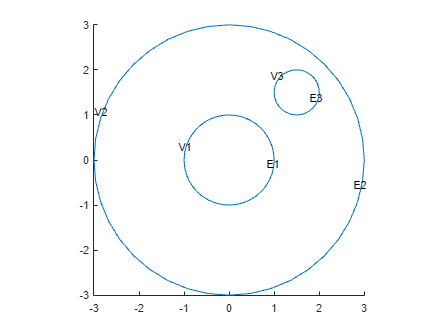

% Sample Equation
% Sloution Benchmark
u    = @(x,y) [sin(x.^2 + y.^2) ;  cos(x.^2 + y.^2)];
Dx_u = @(x,y) [2*x.*cos(x.^2 + y.^2) ; -2*x.*sin(x.^2 + y.^2)]; 
Dy_u = @(x,y) [2*y.*cos(x.^2 + y.^2) ; -2*y.*sin(x.^2 + y.^2)]; 

% System Settings
m  = 2 ;  % number of dependent variables
A1 = @(x,y) [0, 1; 1, 0];
A2 = @(x,y) [-1, 0; 0, 1];
A0 = @(x,y) [2*x, 2*y; 2*y, -2*x];
f  = @(x,y) [0 ; 0];
g  = @(x,y) u(x,y);

% Omega
t = pi/20 : pi/20 : 2*pi;
Omega = polyshape({3*cos(t), 1*cos(t), 1.5+0.5*cos(t)}, {3*sin(t), 1*sin(t), 1.5+0.5*sin(t)});  % polyshape({Gamma1X, ...}, {Gamma1Y, ...})

% Construct the model
model = Collocation2D(m, A1, A2, A0, f, g, Omega, u, Dx_u, Dy_u);
model.gm.pdegplot(VertexLabels="on",EdgeLabels="on");

We approximate the solution with $C^0$ Lagrange elment $\mathrm{CG}_q$ where we first try $q=1$(linear elements). The degrees of freedom are given by evaluating the basis at all local vertices of the element. In element $K$ where $K=\triangle(v^K_1,v^K_2,v^K_3)$ is a trangle defined by three vertices $v^K_i(x^K_i,y^K_i)$, the nodal bases for som $p=(x,y)\in K$ are given by


$$\phi_1^K(p)\ =\ \frac{S_{\triangle}(p,v^K_2,v^K_3)}{S^K},$$



$$\phi_2^K(p)\ =\ \frac{S_{\triangle}(v^K_1,p,v^K_3)}{S^K},$$



$$\phi_3^K(p)\ =\ \frac{S_{\triangle}(v^K_1,v^K_2,p)}{S^K},$$


where 


$$S_{\triangle}(p_1,p_2,p_3)= \frac{1}{2}\left|\matrix{1\ x_1\ y_1\cr
1\ x_2\ y_2\cr
1\ x_3\ y_3  } \right| $$
 

is the area of the triangle $\triangle(p_1,p_2,p_3)$ s.t. $p_i=(x_i,y_i)$ and $p_1\to p_2\to p_3$ is given in a counterclockwise order  so that $S_{\triangle}(p_1,p_2,p_3)>0$; $S^K=S_\triangle(v^K_1,v^K_2,v^K_3)$ is the area of of the element. The solution ansatz is given as


$$\mathbf{u}(x)\approx\mathbf{u_C}(x)=\mathbf{C}\mathbf{\phi}(x)=\sum^n_{i=1}\mathbf{c}_i \cdot\phi_i(x),$$


where $\mathbf{c}_i$ is the $i_{th}$ column of $\mathbf{C}\in\mathbb{R}^{m\times n}$,  $\phi_i(x)$ is the global basis corresponding to the $i_{th}$ global degree of freedom (resp. the $i_{th}$ global vertex $v_i$ forming the discretized mesh). We start by forming a 2D polygonal mesh $\mathcal{M}=\{K_i\}_{i=1}^{M}$ for the domain $\Omega$.

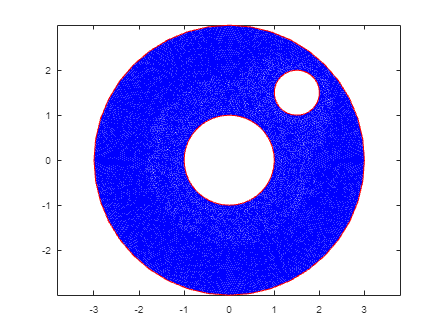

% Discretization
beta = 5 ; hmax=0.05 ;                   % mesh size, hmin=hmax/beta 
model.discretize(hmax, beta, 'linear');  % linear discretization, can be replaced with 'quadratic'
model.gm.pdemesh();                      %(ElementLabels="on", NodeLabels="on") ;

model.gm.Mesh

ans =   FEMesh - 属性:

             Nodes: [2×11724 double]
          Elements: [3×22884 double]
    MaxElementSize: 0.0500
    MinElementSize: 0.0100
     MeshGradation: 1.5000
    GeometricOrder: 'linear'


The above `gm.Mesh.Nodes` stores the $(x,y)$ coordinates for each global vertex. `gm.Mesh.Elements `provides the local-to-global map and local vertices are stored in a counterclockwise order.

The following functions help to sample points from the boundary and the within the domain.

% Coordinates of the closed boundary nodes
rng(42) ;  % random seed

% Sampled boundary nodes of the mesh
% model.interp_polyboundary(boundary_nodes, rs, fixed_Nodes);
% model.interp_polyboundary(boundary_nodes, N, fixed_Nodes);
N_Gamma = 50000

N_Gamma = 50000

% sampled_boundary_nodes = model.interp_polyboundary(mesh_boundary_nodes, N_Gamma);
edge = model.boundary_decompose();
sampled_boundary_nodes = model.interp_multiedge_polyboundary(edge, round(N_Gamma/length(edge)));

% Sampled interior nodes of the mesh
% model.sample_from_triangleMesh(mesh, N_loc, fixed_Nodes) ;
N_loc = 14; % N_loc points per element
sampled_interior_nodes = model.sample_from_triangleMesh(model.gm.Mesh, N_loc, model.gm.Mesh.Nodes');

N_Omega = size(sampled_interior_nodes, 1);
N_Gamma = size(sampled_boundary_nodes, 1);
N = N_Gamma + N_Omega;
fprintf('N_Omega: %d, N_Gamma: %d, N: %d', N_Omega, N_Gamma, N);

N_Omega: 332100, N_Gamma: 50001, N: 382101

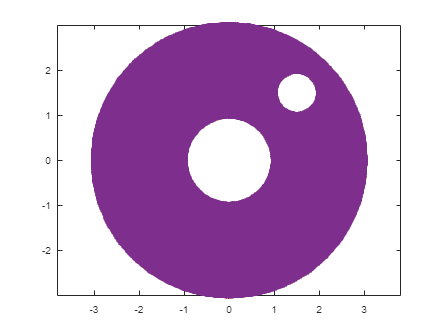


% Plot mesh and sampled points
if true 
    model.gm.pdemesh();
    hold on
    scatter(sampled_interior_nodes(:,1), sampled_interior_nodes(:,2))
    scatter(sampled_boundary_nodes(:,1), sampled_boundary_nodes(:,2), "filled")
    hold off
end

We now try to evaluate the residuals. For a given point $x\in K_i$ with a local-to-global map $\iota_{K_i}(j)=$ `gm.Mesh.Elements(j,i)` where $j=1,2,3$ we can evaluate the interior residuals


$$R_{\Omega}(x)=\mathbf{A}_1\partial_x\mathbf{u}_\mathbf{C}+\mathbf{A}_2\partial_y\mathbf{u}_{\mathbf{C}}+\mathbf{A}_0\mathbf{u}_{\mathbf{C}}-\mathbf{f}(x,y)$$


namely,

$R_{\Omega}(x)=

\left[\matrix{\ 

\mathcal{A}(\phi_1^K)
&
\mathcal{A}(\phi_2^K)
&
\mathcal{A}(\phi_3^K)

\    } \right]

\left[\matrix{ \mathbf{c}_{\iota_K(1)}  \cr  \mathbf{c}_{\iota_K(2)}\cr\mathbf{c}_{\iota_K(3)} } \right]-\mathbf{f}(x,y)$,

where $\mathcal{A}(\phi)=\mathbf{A}_1\partial_x\phi+\mathbf{A}_2\partial_y\phi+\mathbf{A}_0\phi$. Similar for the boundary residuals with weights specified by the diagonal matrix $\Lambda\in\mathbb{R}^{m\times m}$

$R_{\Gamma}(x)=\Lambda[\mathbf{u_C}(x)-\mathbf{g}(x)]
$,

there is 

$R_{\Omega}(x)=

\left[\matrix{\ 

\Lambda\phi_1^K
&
\Lambda\phi_2^K
&
\Lambda\phi_3^K

\    } \right]

\left[\matrix{ \mathbf{c}_{\iota_K(1)}  \cr  \mathbf{c}_{\iota_K(2)}\cr\mathbf{c}_{\iota_K(3)} } \right]-\Lambda\mathbf{g}(x,y)$.

Note if we write 

$\mathbf{B}^K_\Omega(x,y) = \left[\matrix{\ 

\mathcal{A}(\phi_1^K)
&
\mathcal{A}(\phi_2^K)
&
\mathcal{A}(\phi_3^K)

\    } \right]\in\mathbb{R}^{m\times 3m}$ for $x\in\mathrm{int}(\Omega)$, 

$\mathbf{B}^K_\Gamma(x,y) = \left[\matrix{\ 

\Lambda\phi_1^K
&
\Lambda\phi_2^K
&
\Lambda\phi_3^K

\    } \right]\in\mathbb{R}^{m\times 3m}$ for $x\in \Gamma=\partial\Omega$, 

a single point $x$ will generate $m$ lines in the final assembled system $\mathbf{B}\mathbf{c}=\mathbf{d}$ where 

$\mathbf{B}=\left[\matrix{ \mathbf{B}_\Omega  \cr  \mathbf{B}_\Gamma} \right]$ , $\mathbf{c}=\mathrm{vec}(\mathbf{C})=\left[\matrix{ \mathbf{c}_1  \cr  \vdots\cr\mathbf{c}_n} \right]$ , $\mathbf{d}=\left[\matrix{ \mathbf{d}_\Omega  \cr  \mathbf{d}_\Gamma} \right]$

and if we define slice $\mathbf{s}(i)=im-m+1:im$, there is

$\mathbf{B}_{\Omega}(\ \mathbf{s}(i)\ ,\  [\mathbf{s}\circ\iota_K(1) \ ,\  \mathbf{s}\circ\iota_K(2) \ ,\  \mathbf{s}\circ\iota_K(3)]\ ) := \mathbf{B}^K_\Omega(x_i,y_i)$,

$\mathbf{B}_{\Gamma}(\ \mathbf{s}(i)\ ,\  [\mathbf{s}\circ\iota_K(1) \ ,\  \mathbf{s}\circ\iota_K(2) \ ,\  \mathbf{s}\circ\iota_K(3)]\ ) := \mathbf{B}^K_\Gamma(\hat{x}_i,\hat{y}_i)$,

and 

$\mathbf{d}_{\Omega}(\ \mathbf{s}(i)\  ) := \mathbf{f}(x_i,y_i)$,

$\mathbf{d}_{\Gamma}(\ \mathbf{s}(i)\  ) := \Lambda\mathbf{g}(\hat{x}_i,\hat{y}_i)$,

for sets of selected points $\{{p}_i\}_{i=1}^{N_{\Omega}}\subset \Omega$ and $\{{\hat{p}}_i\}_{i=1}^{ N_{\Gamma} } \subset \Gamma$, $N=N_{\Omega}+N_{\Gamma}$.

% System assemble
Lambda = diag(100000*ones(1,m));     % square(weights) for BC
[B_Omega, d_Omega, N_Omega_modified] = model.Assemble_B_Omega(sampled_interior_nodes);
[B_Gamma, d_Gamma, N_Gamma_modified] = model.Assemble_B_Gamma(sampled_boundary_nodes, Lambda);
B = [B_Omega ; B_Gamma]; d = [d_Omega ; d_Gamma];

fprintf('Num Elements: %d, Num Basis: %d', model.ele_num, model.basis_num);

Num Elements: 22884, Num Basis: 11724

fprintf('Modified N_Omega: %d, Modified N_Gamma: %d, Modified N: %d', ...
         N_Omega_modified, N_Gamma_modified, N_Omega_modified + N_Gamma_modified);

Modified N_Omega: 332048, Modified N_Gamma: 50001, Modified N: 382049

We first solve the assembled matrix directly

% load('./data/2DCollocationExample_01.mat');
% B = [model.Omega_assemble.B ; model.Gamma_assemble.B]; 
% d = [model.Omega_assemble.d ; model.Gamma_assemble.d];

c = B\d; % lsqr(B, d, [], 10000)
model.C = model.reshape2mat(c); 
% save('./data/2DCollocationExample_01.mat', 'model');

% Solution evaluation
grid_size = [100, 100]; % [x_size, y_size]
[X, Y, in, XY] = model.OmegaMeshgrid(grid_size);

u_fit  = model.evaluate_LSFEM(XY);
u_true = model.u(XY(:,1)', XY(:,2)');

u_fit  = model.reshapeRowsTo3D(u_fit, grid_size(2), grid_size(1));
u_true = model.reshapeRowsTo3D(u_true, grid_size(2), grid_size(1)) .* in;

X_label = round(X(1,:),2);
Y_label = round(Y(:,1),2);

% Plot output
fprintf('u_1');

u_1

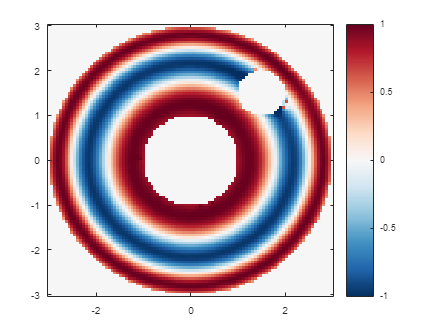

@author : slandarer


imagesc(X_label, Y_label, u_fit(:,:,1));
colorbar;
clim([-1 1]);
set(gca,'YDir','normal');
colormap(flipud(slanCM(97)));

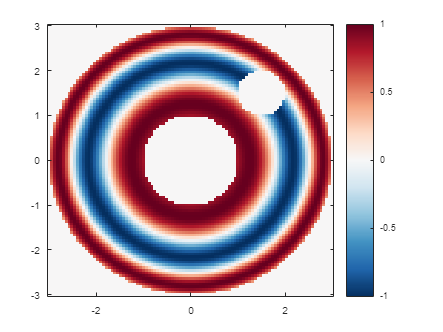


imagesc(X_label, Y_label, u_true(:,:,1));
colorbar;
clim([-1 1]) ;
set(gca,'YDir','normal');

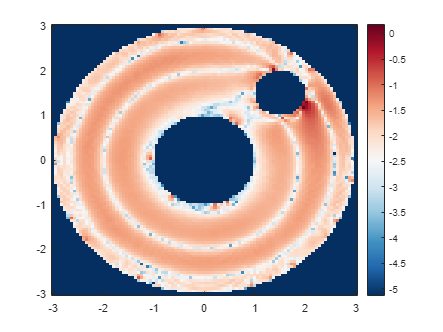


error1 = log10(abs(u_fit(:,:,1) - u_true(:,:,1))); % )./abs(u_true(:,:,1)) ;
imagesc(X_label, Y_label, error1);
colorbar;
%clim([0 0.1]) ;
set(gca,'YDir','normal');


fprintf('u_2');

u_2

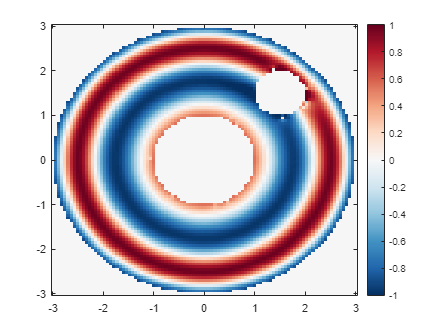

imagesc(X_label, Y_label, u_fit(:,:,2));
colorbar ;
clim([-1 1]);
set(gca,'YDir','normal');

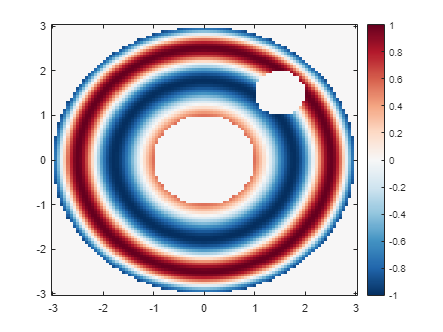


imagesc(X_label, Y_label, u_true(:,:,2));
colorbar;
clim([-1 1]);
set(gca,'YDir','normal');

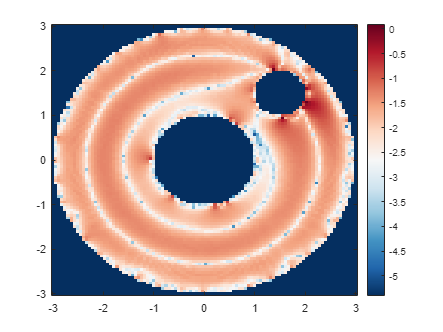


error2 = log10(abs(u_fit(:,:,2) - u_true(:,:,2))); %)./abs(u_true(:,:,2)) ;
imagesc(X_label, Y_label, error2);
colorbar;
%clim([0 0.1]) ;
set(gca,'YDir','normal');